# Coursework: parameter estimation for model calibration and fault identification in water distribution networks

clc
clear
close all

Load properties of STKLnet network, loading conditions and measurements for a period of 8 days. The original roughness coefficients of the hydraulic model are given by `wdn.C`.

load('data\STKLnet_8days_Dataset.mat')
A12 = wdn.A12;
A10 = wdn.A10;
np = wdn.np;
nn = wdn.nn;
n_exp = wdn.n_exp;
C = wdn.C;

Using the hydraulic model and loading conditions provided in the dataset, simulate pressure heads at network nodes.

d = data.d; % customer demands
h0 = data.h0; % reservoir heads
hdata = data.hdata; % measured hydraulic heads at pressure sensors
[~,hsim] = hydraulic_simulation(C,wdn,d,h0);

Compare simulated heads at loggers (node indices in `All_Sensors`) with the corresponding pressure head measurements over the 8-day period (given by `data.hdata`).

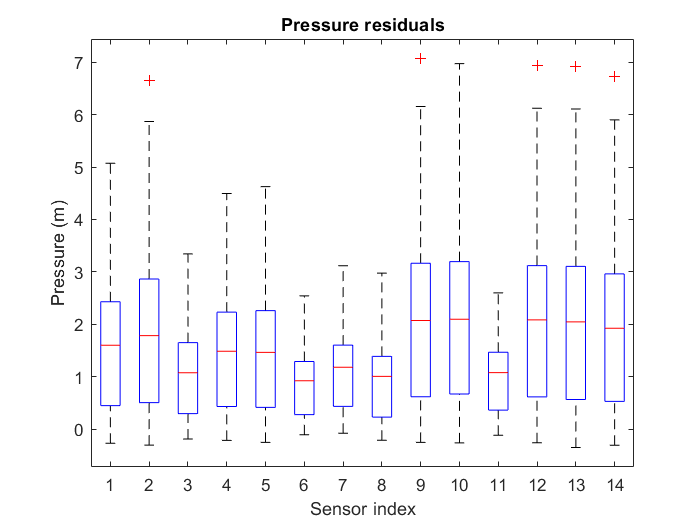

pressure_residuals_8days = hsim(All_Sensors,:) - hdata;
% plot head error residuals on test set
figure,boxplot(pressure_residuals_8days')
xlabel('Sensor index')
ylabel('Pressure (m)')
title('Pressure residuals')

Question 1: Is the current hydraulic model of STKLnet accurate according to the guidelines defined by the Water Research Centre? Justify your answer (e.g. with a figure).

Answer 1: The aim of current hydraulic model of STKLnet is to perform the model calibration and validation, fault detection and identification task (clear statement of aims and objectives). According to WRC guidelines, the accuracy of this model can be guaranteed based on the following.

- Sufficient data has been collected from the source, which increases the accuracy of the model.

- The model for detailed operational use should include pipes with more than 150 mm diameter, in this model, pipes even with less than 100 mm  diameter are also considered, which maximizes its accuracy.

However, its accuracy can not be promised based on the following reasons.

- All work should be subject to quality control, this model has not been checked under quality control assurance.

- The system records and further information, including the drawings, leakage zone meters and pump details etc., are not considered in this model.

- The obvious anomalies, errors, omissions, discrepancies are not checked and corrected in this model.

- The number of nodes which field measurements of pressure are made to calibrate the model should be 15% (desirable) or 10% (at least) the number of nodes in the network. Obviously, the 14 measured nodes can not meet the standard of the guideline.

- According to the guidelines, the roughness coefficient, which is directly connected to the head loss values, is primarily obtained from standard tables and needs to be calibrated (while not in this model), hence this model is theoretically not trustworthy.

- As the demand defined by WRC include the metered demand, leakage and domestic demand, the data in this model does not consider the leakage demand, which represents a significant proportion of the demand, the modelling of the STKLnet is not accurate before calibrating.

- The required field test has not been fully carried out. The flows and pressures modelled must be compared with measured data and field test data to be representative of the real system.

- Most importantly, the guideline clearly stated the following: 1. Modelled trunk main flows (more than 10% of total demand) should be within 5% difference of the measured flows. 2. Modelled trunk main flows (less than 10% of total demand) should be within 10% difference of the measured flows. 3. 85% of the field test measurements should be within 0.5 m or 5% of maximum head loss across system whichever is greater. 4. 95% of the field test measurements should be within 0.75 m or 7.5% of maximum head loss across system whichever is greater. 5. 100% of the field test measurements should be within 2.0 m or 15% of maximum head loss across system whichever is greater.

Therefore, generally, this model is to some extent useful, but its accuracy is at a relatively low level, we can plot the pressure head at node 1 to see the difference between the simulated pressures and pressures in the real system.

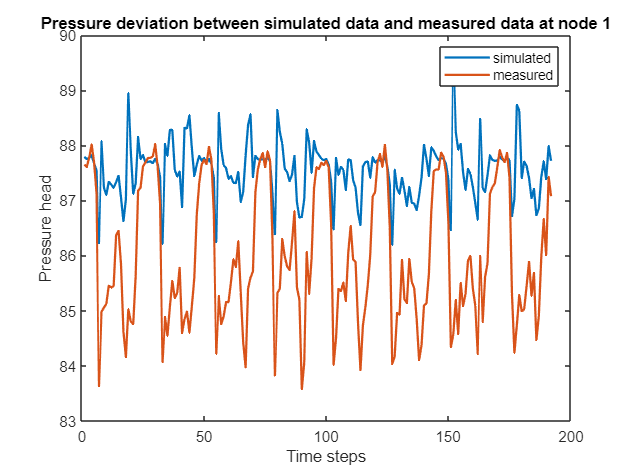

% plot the simulated and measured data
% Take node 1 as an example
hsim_sensors = hsim(All_Sensors,:);
hsim_sensors_1 = hsim_sensors(1,:);
hdata_sensors_1 = hdata(1,:);

% plot the result of comparison
figure,
plot(1:size(hsim_sensors_1,2),hsim_sensors_1,'LineWidth',1.5);
hold on
plot(1:size(hsim_sensors_1,2),hdata_sensors_1,'LineWidth',1.5);
legend({'simulated','measured'})
xlabel('Time steps')
ylabel('Pressure head')
title('Pressure deviation between simulated data and measured data at node 1')

Obviously, there is a big difference between the simulated data and the measured data, which is also in line with the boxplot 'Pressure residuals'. Moreover, we can calculate the deviation between the simulated and measured data to support this result. The obtained mean squared error is 3.9393, which is too large to be considered accpted.

% calculate the deviation
loss_fun_q1 = @(h) (1/length(hdata(:)))*sum(sum( (h(All_Sensors,:) - hdata).^2));
loss_q1 = loss_fun_q1(hsim);

Besides, according to WRC guidelines, as we have the pressure measurement data, we can test whether 100% of the nodes are in the acceptance zone.

% difference between modelled pressures against recorded field data
pressure_diff_sum = zeros(1,4);
for i = 1:size(pressure_residuals_8days,1)
    for j = 1:size(pressure_residuals_8days,2)
        if abs(pressure_residuals_8days(i,j)) <= 0.5
            pressure_diff_sum(1,1) = pressure_diff_sum(1,1)+1;
        elseif 0.5 < abs(pressure_residuals_8days(i,j)) && ...
            abs(pressure_residuals_8days(i,j)) <= 0.75
            pressure_diff_sum(1,2) = pressure_diff_sum(1,2)+1;
        elseif 0.75 < abs(pressure_residuals_8days(i,j)) && ...
            abs(pressure_residuals_8days(i,j)) <= 2
            pressure_diff_sum(1,3) = pressure_diff_sum(1,3)+1;
        else
            pressure_diff_sum(1,4) = pressure_diff_sum(1,4)+1;
        end
    end
end
pressure_diff_sum_percent = pressure_diff_sum.*100./(size(pressure_residuals_8days,1)* ...
    size(pressure_residuals_8days,2));
Table_pressure_diff_beforecalibration = table(pressure_diff_sum_percent(1,1), ...
    pressure_diff_sum_percent(1,2), ...
    pressure_diff_sum_percent(1,3),pressure_diff_sum_percent(1,4),'VariableNames', ...
    {'Less than 0.5m','0.5m to 0.75m', ...
    '0.75m to 2m','More than 2m'},'RowNames',{'Proportion/%'});
display(Table_pressure_diff_beforecalibration);

Table_pressure_diff_beforecalibration = 1×4 table
                    Less than 0.5m    0.5m to 0.75m    0.75m to 2m    More than 2m
                    ______________    _____________    ___________    ____________

    Proportion/%        26.451           5.2827          36.198          32.068   


As we can see, approximately 32% of the node pressure residuals are more 2 m, largely higher than the standard set by WRC. Only 26% of the node pressure residuals are less than 0.5%, which should be more than 85% according to the WRC criteria.

Finally, we can confidently draw the conclusion that the current model is not accurate enough to be applied to the network operation, maintenance and fault detection.

## Part 1: Hydraulic model calibration and validation

Based on the initial comparison between pressure measurements and simulated pressures at the network nodes, we propose to calibrate the hydraulic model of STKLnet. Complete the code below to calibrate the network model using the 8 days worth of data provided in `'STKLnet_8days_Dataset.mat'`. 

#### Separate train and test data

We use the first day worth of data (loading conditions + measurements) as a train dataset (`dataTrain`), and the remaining 7 days as a test dataset (`dataTest`).

dataTrain.d = d(:,1:24);
dataTrain.h0 = h0(:,1:24);
dataTrain.hdata = hdata(:,1:24);
dataTest.d = d(:,25:size(d,2));
dataTest.h0 = h0(:,25:size(d,2));
dataTest.hdata = hdata(:,25:size(d,2));

### Task 1: model calibration

#### Solve a parameter estimation problem using the train dataset

d = dataTrain.d;
h0 = dataTrain.h0;
hdata = dataTrain.hdata;
nt = size(d,2); % nt is the number of time steps

% define the loss function (deviations between simulated and measured
% pressures at sensor locations All_Sensors)
loss_fun = @(h) (1/length(hdata(:)))*sum(sum( (h(All_Sensors,:) - hdata).^2));

%%% Setting up parameters for the sequential convex programming algorithm:
Deltak = 20;
Ki = Inf;
IterMax = 50;

% initialize the estimate (hk,qk,thetak) and trust region Deltak
thetak = wdn.C;
[qk,hk] = hydraulic_simulation(thetak,wdn,d,h0);
objvalk = loss_fun(hk);

% and the matrices for the linear approximation of the frictional
% headloss around solution xk=(hk,qk,thetak)
[a11k, bk] = linear_approx_calibration(wdn,qk,thetak);

for k = 1:IterMax
    cvx_begin quiet
        cvx_solver_settings('stoplevel',0)
        variable h(nn,nt)
        variable q(np,nt)
        variable theta(np,1)
        minimize(loss_fun(h))
        subject to
        for t=1:nt
            a11k(:,t).*qk(:,t) + n_exp.*a11k(:,t).*q(:,t) + bk(:,t).*theta + A12*h(:,t)...
            + A10*h0(:,t) == 0
            A12'*q(:,t) == d(:,t)
        end
        norm(theta - thetak,Inf) <= Deltak;
        0 <= theta <= 200;
    cvx_end
    
    % temporary estimates of the roughness coefficients theta, 
    theta_tilde = theta;
    % as well as flows and heads, q and h, 
    [q_tilde,h_tilde] = hydraulic_simulation(theta_tilde,wdn,d,h0);
    % and the objective function objval
    objval_tilde = loss_fun(h_tilde); % = phi_tilde
    
    if (objvalk - objval_tilde)/cvx_optval >= 0.01
        % if the iteration is successful, store objvalk
        objval_old = objvalk;
        % and update thetak, qk, hk and objvalk with latest estimates
        thetak = theta_tilde;
        qk = q_tilde;
        hk = h_tilde;
        objvalk = objval_tilde;
        
        % compute the matrices for the linear approximation of the frictional
        % headloss around the new estimate (hk,qk,thetak)
        [a11k, bk] = linear_approx_calibration(wdn,qk,thetak);
        
        Ki = abs(objval_old - objvalk)/abs(objval_old);
        % increase the size of the trust region by 10%
        Deltak = 1.1*Deltak;
    else
        % if the iteration is unsuccessful, do not update the current best
        % estimates thetak, qk and hk, but decrease the size of the trust
        % region by half
        Deltak = 0.5*Deltak;
    end
    
    if Ki<=1e-3 || abs(objvalk)<=1e-2 || Deltak<=1e-2
        % when termination conditions are met
        break
    end
end

NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
-----------------------------------

### Task 2: model validation

#### Evaluate final model error on the test dataset

Using the calibrated roughness coefficients, simulate hydraulic conditions for the loading data in the test dataset (`dataTest.d `and `dataTest.h0`) and compare simulated heads at pressure sensors (`All_Sensors`) to the corresponding measurements (`dataTest.hdata`).

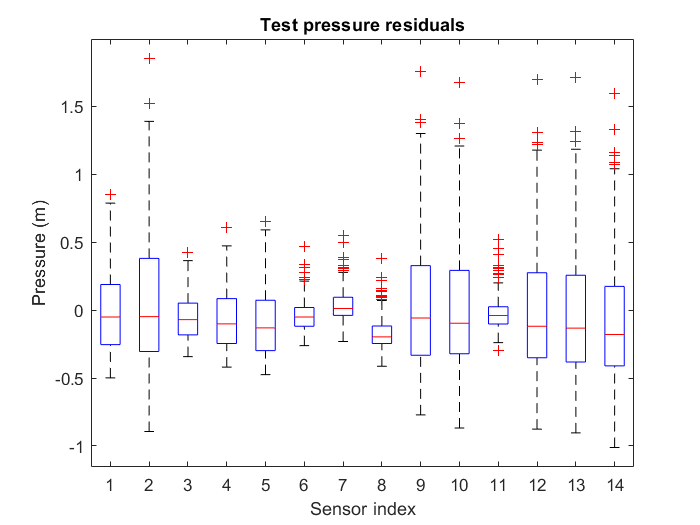

% update network model with new roughness coefficients
wdn.C = theta;

% simulate pressure heads with loading conditions corresponding to dataTest
% (test dataset)
[q_test,h_test] = hydraulic_simulation(wdn.C,wdn,dataTest.d,dataTest.h0);
% compute final error on test set
mse_test_fun = @(h) (1/length(dataTest.hdata(:)))*sum(sum( (h(All_Sensors,:) - dataTest.hdata).^2));
final_mse_test = mse_test_fun(h_test);
% compute pressure residuals
final_residuals_test = h_test(All_Sensors,:) - dataTest.hdata;

% plot head error residuals on test set
figure,boxplot(final_residuals_test')
xlabel('Sensor index')
ylabel('Pressure (m)')
title('Test pressure residuals')

Question 2: Comment on the improvement in model accuracy (before v.s. after calibration). According to the guidelines defined by the Water Research Centre (i.e. simulated heads within 2m of measurements), can the new model be considered "calibrated"? Cite at least one of the advantages, for the network operator, of using a calibrated hydraulic model of STKLnet.

Answer 2: The improvement in model accuracy after calibration is very obvious, from the mean squared error we can easily see that, after calibration, the final mse value is only 0.1212, compared with the 3.9393 before calibration, it significantly decreases, which means the pressure head difference between measured data and simulated data also dramatically decreases. Therefore, we can draw a bar plot to see how it changes after calibration, which is based on the WRC guidelines.

% difference between modelled pressures against recorded field data
pressure_diff_sum_test = zeros(1,4);
for i = 1:size(final_residuals_test,1)
    for j = 1:size(final_residuals_test,2)
        if abs(final_residuals_test(i,j)) <= 0.5
            pressure_diff_sum_test(1,1) = pressure_diff_sum_test(1,1)+1;
        elseif 0.5 < abs(final_residuals_test(i,j)) && abs(final_residuals_test(i,j)) <= 0.75
            pressure_diff_sum_test(1,2) = pressure_diff_sum_test(1,2)+1;
        elseif 0.75 < abs(final_residuals_test(i,j)) && abs(final_residuals_test(i,j)) <= 2
            pressure_diff_sum_test(1,3) = pressure_diff_sum_test(1,3)+1;
        else
            pressure_diff_sum_test(1,4) = pressure_diff_sum_test(1,4)+1;
        end
    end
end
pressure_diff_sum_test_percent = pressure_diff_sum_test.*100./(size(final_residuals_test,1) ...
    *size(final_residuals_test,2));

% create a table to show the result
Table_pressure_diff_beforecalibration = table(pressure_diff_sum_test_percent(1,1), ...
    pressure_diff_sum_test_percent(1,2), ...
    pressure_diff_sum_test_percent(1,3),pressure_diff_sum_test_percent(1,4), ...
    'VariableNames',{'Less than 0.5m','0.5m to 0.75m', ...
    '0.75m to 2m','More than 2m'},'RowNames',{'Proportion/%'});
display(Table_pressure_diff_beforecalibration);

Table_pressure_diff_beforecalibration = 1×4 table
                    Less than 0.5m    0.5m to 0.75m    0.75m to 2m    More than 2m
                    ______________    _____________    ___________    ____________

    Proportion/%        89.201           6.6327          4.1667            0      


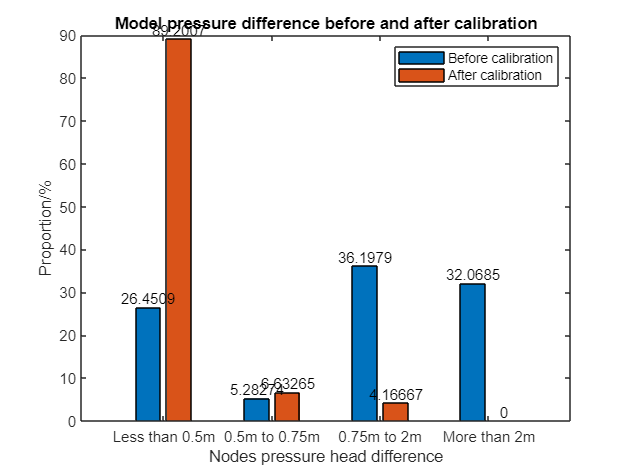


% plot the bar chart to show the difference between two models
X_pressure_calibration = categorical({'Less than 0.5m','0.5m to 0.75m','0.75m to 2m', ...
    'More than 2m'});
X_pressure_calibration = reordercats(X_pressure_calibration,{'Less than 0.5m', ...
    '0.5m to 0.75m','0.75m to 2m','More than 2m'});
Y_pressure_calibration = zeros(2,4);
for i_bar = 1:4
        Y_pressure_calibration(1,i_bar) = pressure_diff_sum_percent(1,i_bar);
        Y_pressure_calibration(2,i_bar) = pressure_diff_sum_test_percent(1,i_bar);
end

pressure_calibration_bar = bar(X_pressure_calibration, Y_pressure_calibration);
xtips1 = pressure_calibration_bar(1).XEndPoints;
ytips1 = pressure_calibration_bar(1).YEndPoints;
labels1 = string(pressure_calibration_bar(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

xtips2 = pressure_calibration_bar(2).XEndPoints;
ytips2 = pressure_calibration_bar(2).YEndPoints;
labels2 = string(pressure_calibration_bar(2).YData);
text(xtips2,ytips2,labels2,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
legend({'Before calibration','After calibration'})
xlabel('Nodes pressure head difference')
ylabel('Proportion/%')
title('Model pressure difference before and after calibration')

From the bar chart, we can see that the nodes pressure head difference between simulated data and measured data is decreased after model calibration, and the result shows that there are about 89.2% of the nodes have pressure head difference less than 0.5 m, which satisfies the guideline set by WRC (85% of the field test measurements should be within 0.5 m or 5% of maximum head loss across system whichever is greater), 95.8% less than 0.75m (WRC: 95%), 100% less than 2.0 m (WRC: 100%), hence the model can be considered 'calibrated'. The advantages of using calibrated hydraulic model of STKLnet include the following.

- A calibrated network model behaviour is representative of the real system without serious discrepancies, which can help the operational staff to take action based on the model prediction with confidence.

- If the network model is calibrated, the anomalies can be attributed to physical discrepancy between what exists in the system and what has been recorded as information when constructing the model. In other words, the calibrated model with high reliability can help us to find out where the fault in the system is, as we do not need to worry about the possibility that the deviation between simulated data and measured data is due to the wrong model simulation.

- The calibrated model can be easily updated for future use, the changes in physical system can be directly reflected in the calibrated model without further correction.

## Part 2: Fault detection and identification

When we have new roughness coefficients $C$ for which the differences between simulated and measured pressures in SKLnet are small enough, we can use the calibrated model to carry out planning or routine network maintenance operations. In particular, if we have reasonably good confidence in the hydraulic model, we can interpret larger deviations between measured and simulated data as unknown changes in the physical system, e.g. a fault. These faults can be located by solving another parameter estimation problem, where a term penalizing large deviations from calibrated coefficients is added to the objective function. Pipes where the largest deviations are observed between the calibrated roughness coefficients (found in Step 1) and the new roughness coefficient estimates are likely to be affected by a fault, the nature of which requires further on-site invetsigation.

In the second part of this coursework, you are given a dataset with customer demands and pressure measurements at the same 14 sensors locations as in Step 1, corresponding to a period of 1 month following the dataset used for the calibration of the hydraulic model. Based on the pressure measurements in the new dataset, fill in the code below to evaluate whether any faults occurred in STKLnet over the period of time covered by the dataset.

### Task 1: (Manual) fault detection 

In this first task, you will manually inspect the dataset corresponding to the pressure measurements collected by the sensors in STKLnet over a period of 1 month and report any fault which has occurred in STKLnet over this period of time. 

Compare pressure measurements in the new dataset against pressures simulated over the same period of time using the calibrated network model and loading conditions in the new dataset. 

Suggestion: We first compare simulated pressures and pressure measurements in the dataset week by week, then day by day, before considering an automated approach.

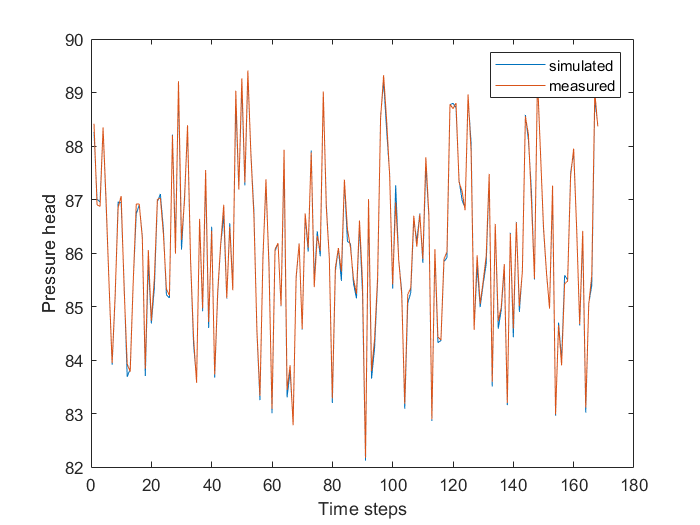

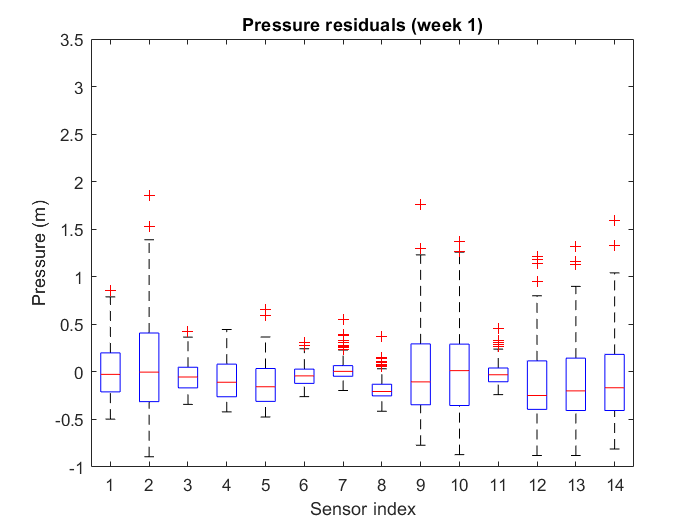

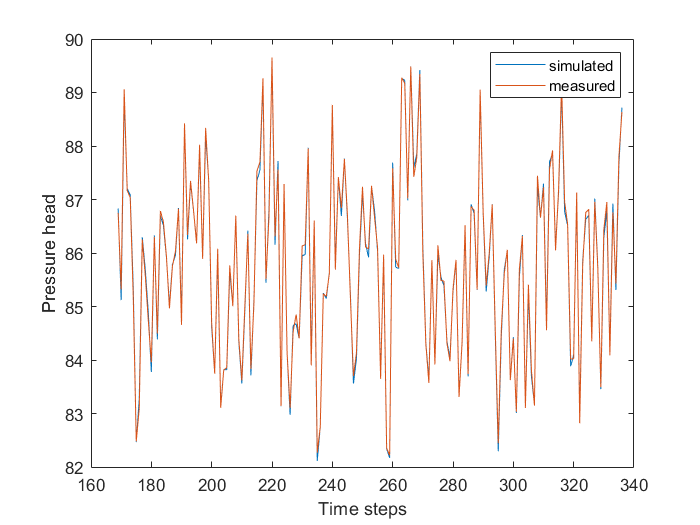

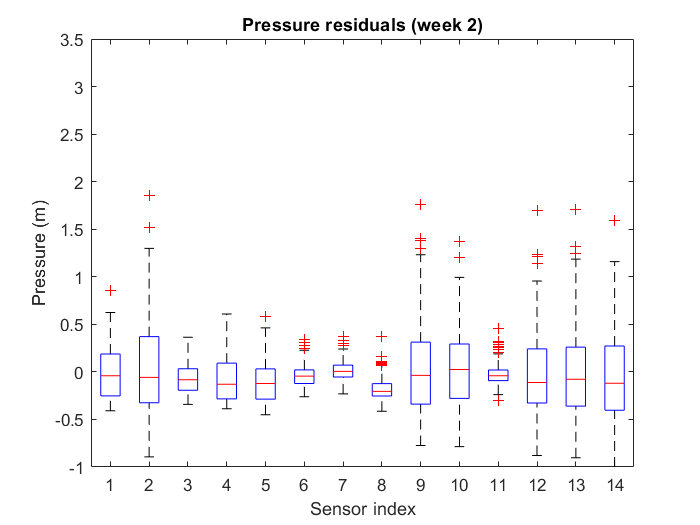

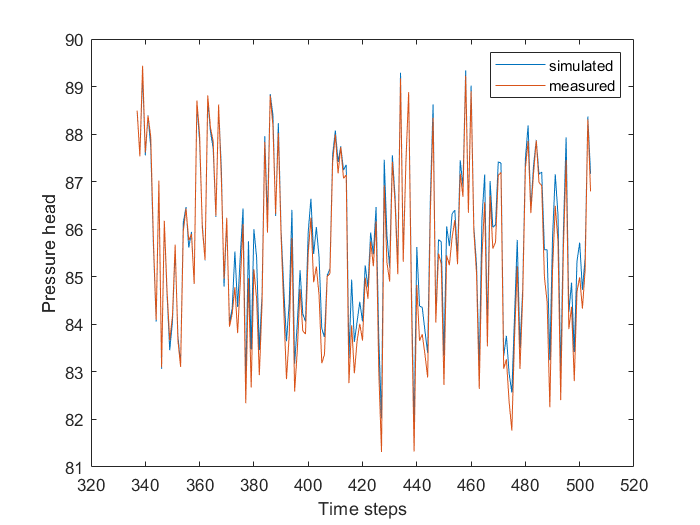

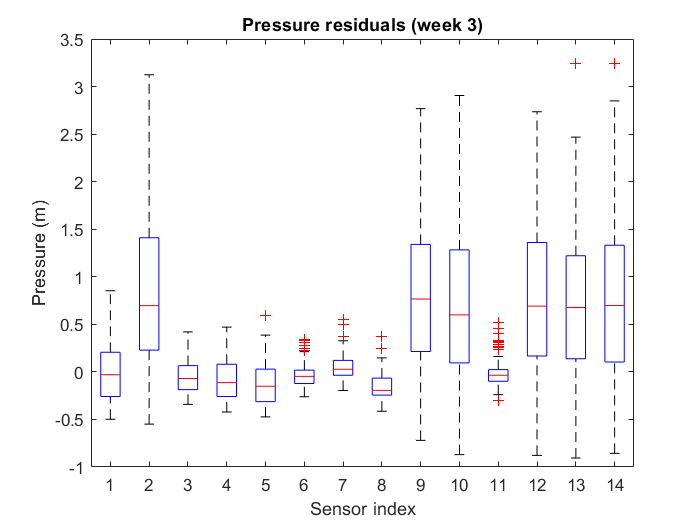

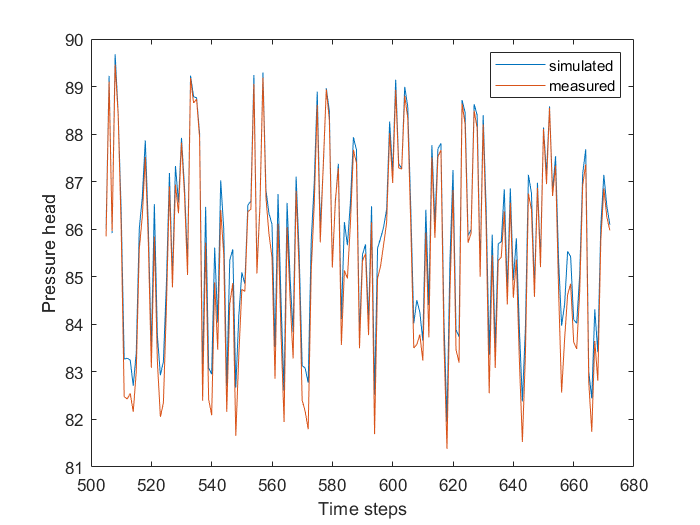

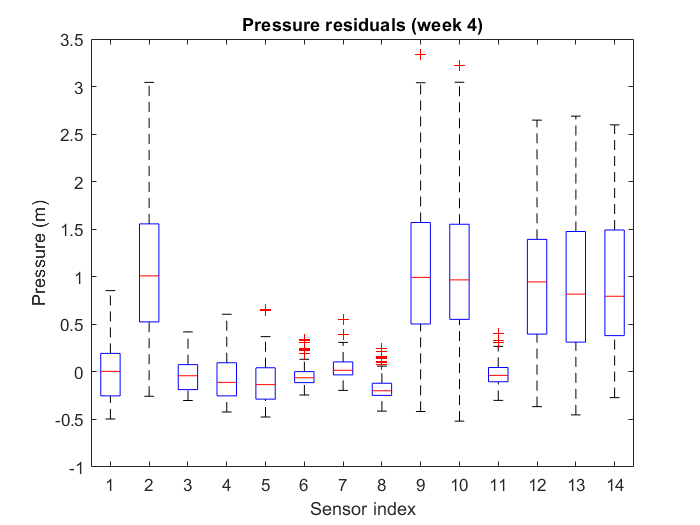

load('data\STKLnet_1month_Dataset.mat','dataFault');
hdata = dataFault.hdata;

% simulate pressure heads over the period of time corresponding to the
% dataset dataFault
[~,hsim] = hydraulic_simulation(wdn.C,wdn,dataFault.d,dataFault.h0);

% define the range of time steps corresponding to a given week
weekly_time_steps = @(week) (week-1)*7*24+1:week*7*24;
% evaluate the mean squared error between measured and simulated pressures,
% first week by week
weekly_mse = zeros(1,4);

for week = 1:4 
    % load pressure heads corresponding to a given week
    hdata_week = hdata(:,weekly_time_steps(week));
    hsim_week = hsim(:,weekly_time_steps(week));
    
    % define a loss function for the corresponding pressure measurements
    fault_mse = @(h) (1/length(hdata_week(:)))*sum(sum( (h(All_Sensors,:) - hdata_week).^2 ));
    
    % compute mean squared error and pressure residuals 
    weekly_mse(1,week) = fault_mse(hsim_week);
    weekly_fault_residuals = hsim_week(All_Sensors,:) - hdata_week;
    
    % plot the measured head and simulated head of each week
    figure,
    plot(weekly_time_steps(week),mean(hsim_week(All_Sensors,:)));
    hold on
    plot(weekly_time_steps(week),mean(hdata_week));
    legend({'simulated','measured'})
    xlabel('Time steps')
    ylabel('Pressure head')

    % plot head error residuals on test set
    figure,boxplot(weekly_fault_residuals')
    xlabel('Sensor index')
    ylabel('Pressure (m)')
    % use a fixed y-scale to help with comparisons
    ylim([-1 3.5])
    title(['Pressure residuals (week ',num2str(week),')'])
end

Identify the first week of irregularities in pressure measurements, i.e. larger deviations between simulated and measured pressures at sensor locations. Justify your answer using the computed mean squared errors or plots of pressure deviations.

% based on the weekly mse data, the week with largest mse is more possible
% to be the faulty week
fault_week = 3;

As the computed mean squared errors of pressure deviations are 0.1168, 0.1250, 0.5567 and 0.6960 for the four weeks, respectively, there is a sudden increase from the week 2 to week 3, and from the boxplot of week 2, we can see that most of the pressure deviations are around 0, but from week 3 on, it suddenly increases, and the pressure residuals at node sensors 2, 9, 10, 12, 13 and 14 also increase, which indicates the fault happens.

Within this first week of deviations between simulation and measurements, identify the first day of deviations.

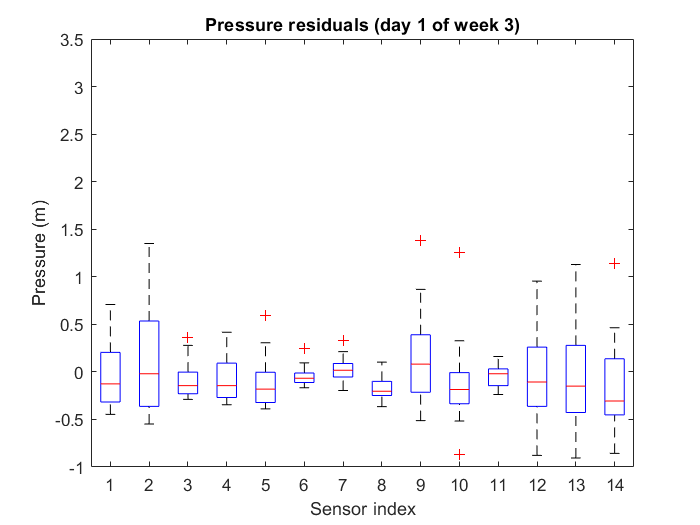

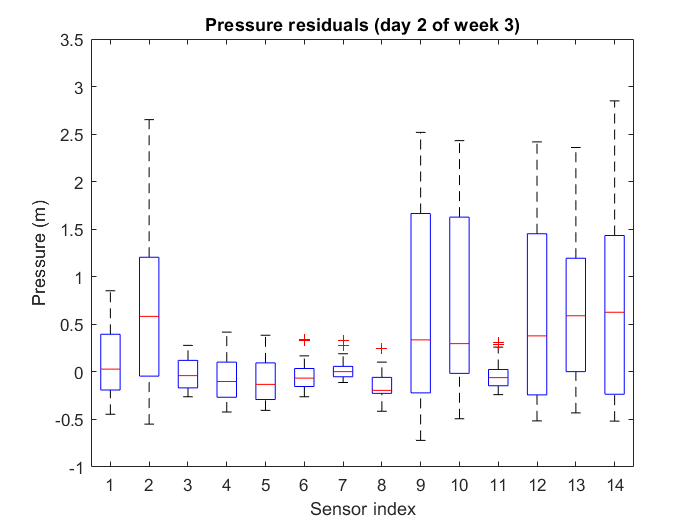

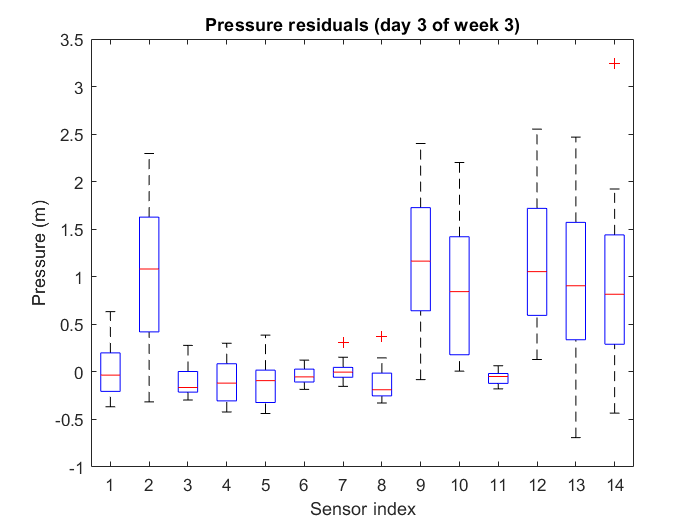

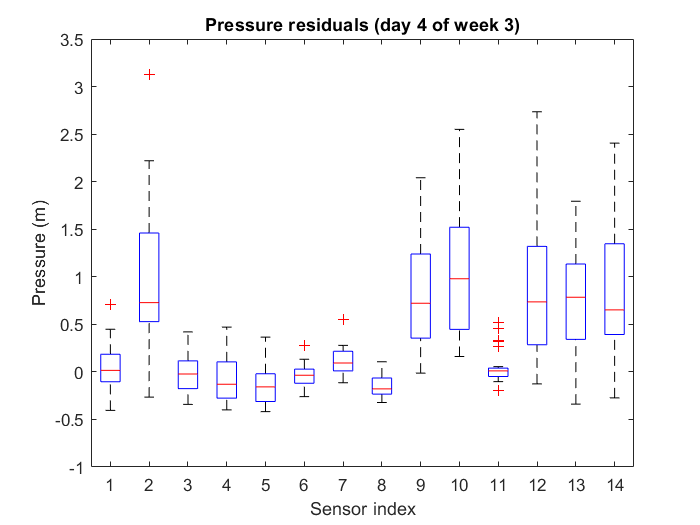

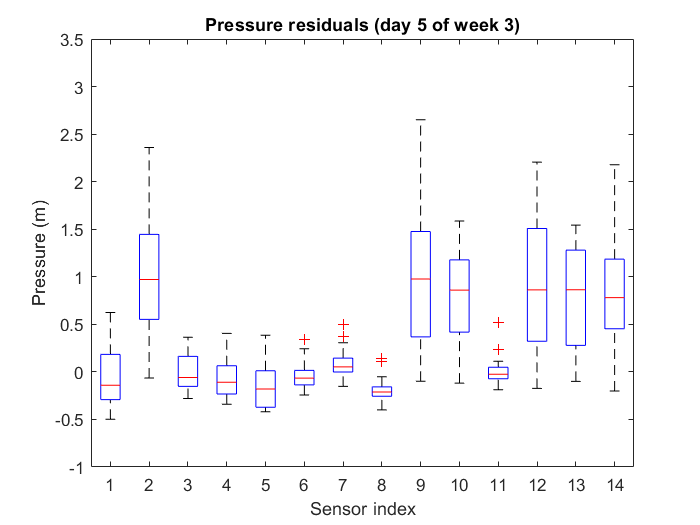

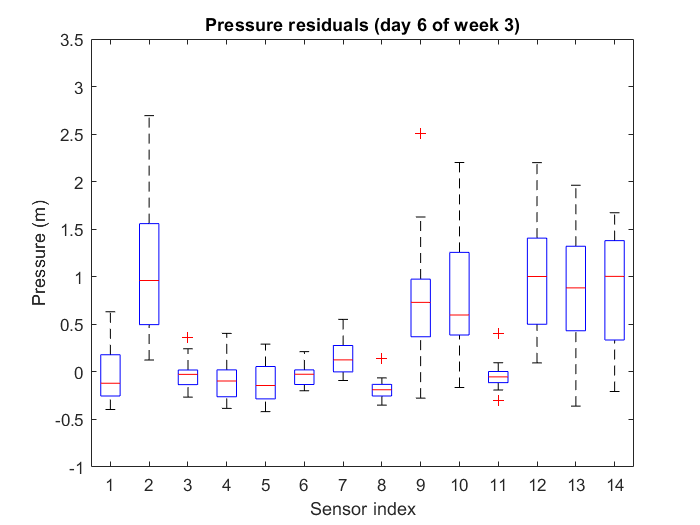

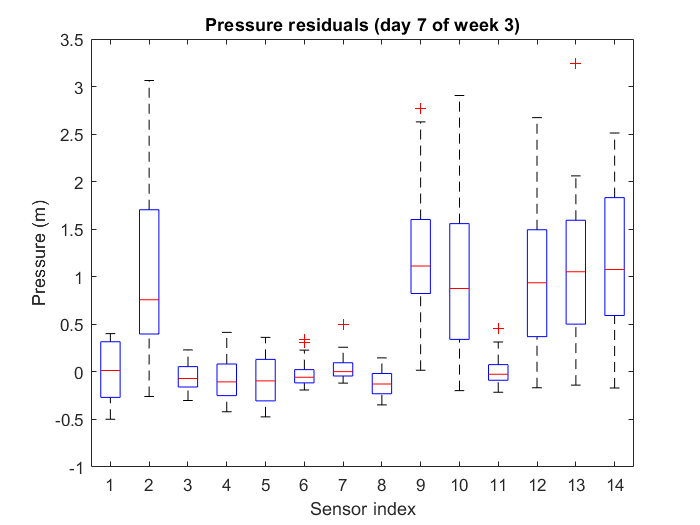

% load data corresponding to the first week of the fault
hdata_week = hdata(:,weekly_time_steps(fault_week));
hsim_week = hsim(:,weekly_time_steps(fault_week));

% define the range of time steps corresponding to a given week
daily_time_steps = @(day) (day-1)*24+1:day*24;
% evaluate the mean squared error between measured and simulated pressures
% day by day
daily_mse = zeros(1,7);

for day = 1:7
    % load pressure heads corresponding to a given day
    hdata_day = hdata_week(:,daily_time_steps(day));
    hsim_day = hsim_week(:,daily_time_steps(day));
    
    % define a loss function for the corresponding pressure measurements
    fault_mse = @(h) (1/length(hdata_day))*sum(sum( (h(All_Sensors,:) - hdata_day).^2 ));
    
    % compute mean squared error and pressure residuals 
    daily_mse(1,day) = fault_mse(hsim_day);
    daily_fault_residuals = hsim_day(All_Sensors,:) - hdata_day;
    
    % plot head error residuals on test set
    figure,boxplot(daily_fault_residuals')
    xlabel('Sensor index')
    ylabel('Pressure (m)')
    ylim([-1 3.5])
    title(['Pressure residuals (day ',num2str(day),' of week ',num2str(fault_week),')'])
end

Identify the first day of irregularities in pressure measurements in `fault_week`. Justify your answer using the computed mean squared errors or plots of pressure deviations.

fault_day = 2;

As the computed mean squared errors of pressure deviations are 1.7041, 8.0180, 10.0792, 7.7810, 7.4514, 7.8306 and 11.6875 for the seven days, respectively, hence the day 2 with largest increased mse value is much more possible to be the fault day.

Question 3: Comment on and propose a justification for the distribution of values of pressure deviations. (Hint: Are they evenly distributed around 0? Or, equivalently, does the fault result in the hydraulic model over or underestimating pressure heads?  and headloss across network pipes?)

Answer 3: First of all, from the following equation, we can find out that the pressure deviation, no matter more or less than 0, will contribute to the deviation of network model equally, thus we need to further explore the deviation problem as below.


$$h_{\textrm{loss}} =\frac{1}{n_t \left|S\right|}\sum_{t=1}^{n_t } \sum_{i\in S} {\left(h_i \left(t\right)-\bar{h_i \left(t\right)} \right)}^2$$


According to the boxplot, the distribution values of pressure deviations are not evenly distributed around 0. And the absolute pressure residual values more than zero are larger than the absolute values less than zero. Therefore, we can calculate the mean value of the data more than zero and less than zero to find out where the problem is.

% The number of pressure residual values (more than 0 or less than 0)
whole_fault_residuals = hsim(All_Sensors,:) - hdata;
Number_whole = zeros(1,2);
Sum_whole = zeros(1,2);
for i_weekly = 1:size(whole_fault_residuals,1)
    for j_weekly = 1:size(whole_fault_residuals,2)
        if whole_fault_residuals(i_weekly,j_weekly) >= 0
            Number_whole(1,1) = Number_whole(1,1) + 1;
            Sum_whole(1,1) = Sum_whole(1,1) + whole_fault_residuals(i_weekly,j_weekly);
        else
            Number_whole(1,2) = Number_whole(1,2) + 1;
            Sum_whole(1,2) = Sum_whole(1,2) + whole_fault_residuals(i_weekly,j_weekly);
        end
    end
end
Mean_whole = Sum_whole./Number_whole;
Pressure_diff_distribution = [Number_whole; Sum_whole; Mean_whole];
Table_pressure_diff_distribution = table(Pressure_diff_distribution(:,1), ...
    Pressure_diff_distribution(:,2), ...
    'VariableNames',{'More than 0', 'Less than 0'},'RowNames',{'Number','Sum','Mean'});
display(Table_pressure_diff_distribution);

Table_pressure_diff_distribution = 3×2 table
              More than 0    Less than 0
              ___________    ___________

    Number         4549           4859  
    Sum          2535.8        -1002.3  
    Mean        0.55744       -0.20628  


From the table we can see that, the number of pressure deviation (More than 0) is slightly smaller than the pressure deviation (Less than 0), which demonstrates that the number of pressure deviation more or less than 0 are close to even distribution. However, the mean value of pressure deviation (More than 0) is 0.5574, which is much higher than the absolute value of pressure deviation (More than 0) (0.2063), thus we can draw the conclusion that the hydraulic model tend to overestimate the pressure heads in the STKLnet network system, and underestimate the head loss, which proves that there is a fault in the system that causes rougher pipes and more head losses. Generally, if there is no fault occurs, the pressure residuals will be evenly distributed around 0.

However, the fault leads to a rougher pipe and increases the head loss, which means pressure residual values tend to be possitive because the measured pressure head will be lower due to the fault. In a conclusion, the day that pressure residuals at sensors suddenly increase is the day when the fault most possibly happens and the abnormal nodes or the pipes connected to them are the places that the fault may exist.

Based on the above assumptions, I choose the second day of week three as the day that the fault occurs and the nodes with abnormal pressure residual values as the faulty place.

### Task 1.1 (optional): automated fault detection

How could the fault detection process be automated to analyse pressure measurements (day by day) and detect faults in the network? Propose an implementation below (based on oberved values of `daily_mse` before and after the fault in Task 1) and test it on the provided dataset, `dataFault`.

To complete this section, simply uncomment the code below and fill it in. Alternatively, it is possible to skip this task by leaving it commented out.

% define mse tolerance and initialise mse and day values
% As the mse before fault is approximately below 2 and more than 8 after
% fault occurs, here we choose 5 as the tolerance
fault_tol_mse = 5;
mse = 0;
day = 0;

Accroding to the mse we have calculated, the mse is mainly below 5 before fault, while much higher than 5 after the fault happens, thus we set 5 as the fault tolerance in this STKLnet system.

% define time steps corresponding to a given day
daily_time_steps = @(day) (day-1)*24+1:day*24;

% loop on day until mse is larger than tolerance
while mse <= fault_tol_mse
    day = day + 1;
    hdata_day = hdata(:,daily_time_steps(day));
    fault_mse = @(h) (1/length(hdata_day))*sum(sum( (h(All_Sensors,daily_time_steps(day)) ...
        - hdata_day).^2 ));
    [~,hsim_day] = hydraulic_simulation(theta,wdn,dataFault.d,dataFault.h0);
    mse = fault_mse(hsim_day);
end

fprintf(['First deviations in pressures occur on day ',num2str(day-floor((day-1)/7)*7), ...
    ' of week ',num2str(ceil(day/7)),'.\n'])

First deviations in pressures occur on day 2 of week 3.


### Task 2: Fault identification

In this second task, you will try to identify the fault detected in Task 1 by solving a parameter estimation problem. As in part 1 (model calibration), use one day worth of data (loading conditions + measurements) to run the parameter estimation problem.

% define time step of fault start
faultStart = (fault_week-1)*7*24+(fault_day-1)*24;

% load loading conditions and pressure head measurements for a period of 1
% day starting from faultStart
d = dataFault.d(:,faultStart+1:faultStart+24);
h0 = dataFault.h0(:,faultStart+1:faultStart+24);
hdata = dataFault.hdata(:,faultStart+1:faultStart+24);

Solve the model calibration problem to compute new roughness coefficients.

% define the loss function 
loss_fun = @(h) (1/length(hdata))*sum(sum( (h(All_Sensors,:) - hdata).^2));
% and a penalty function penalizing large deviations in the roughness coefficients
penalty_fun = @(theta) 0.1*(1/np)*norm(theta - wdn.C,1); 

%%% Setting up parameters for the sequential convex programming algorithm:
Deltak = 10;
Ki = Inf;
IterMax = 50;

% initialize the estimate (hk,qk,thetak), trust region Deltak and objective
% value objvalk
thetak = theta;
[qk,hk] = hydraulic_simulation(thetak,wdn,d,h0);
objvalk = loss_fun(hk) + penalty_fun(thetak);

% and the matrices for the linear approximation of the frictional
% headloss around solution xk = (hk,qk,thetak)
[a11k, bk] = linear_approx_calibration(wdn,qk,thetak);

for k = 1:IterMax
    cvx_begin quiet
        cvx_solver_settings('stoplevel',0)
        variable h(nn,nt)
        variable q(np,nt)
        variable theta(np,1)
        minimize(loss_fun(h) + penalty_fun(theta))
        subject to
        for t=1:nt
            a11k(:,t).*qk(:,t) + n_exp.*a11k(:,t).*q(:,t) + bk(:,t).*theta + A12*h(:,t) ...
            + A10*h0(:,t) == 0
            A12'*q(:,t) == d(:,t)
        end
        norm(theta - thetak,Inf) <= Deltak;
        0 <= theta <= 200;
    cvx_end
    
    theta_tilde = theta;
    [q_tilde,h_tilde] = hydraulic_simulation(theta_tilde,wdn,d,h0);
    objval_tilde = loss_fun(h_tilde) + penalty_fun(theta_tilde);
    
    if (objvalk - objval_tilde)/cvx_optval >= 0.01
        objval_old = objvalk;
        
        thetak = theta_tilde;
        qk = q_tilde;
        hk = h_tilde;
        objvalk = objval_tilde;
        
        [a11k, bk] = linear_approx_calibration(wdn,qk,thetak);
        Ki = abs(objval_old - objvalk)/abs(objval_old);
        
        Deltak = 1.1*Deltak;
    else
        Deltak = 0.5*Deltak;
    end
    
    if Ki<=1e-3 || abs(objvalk)<=1e-2 || Deltak<=1e-2
        break
    end
end

NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
------------------------------------------------------------
NOTE: custom settings have been set for this solver.
-----------------------------------

Compute deviations in `theta` from calibrated roughness coefficients $C$.

delta_theta = theta - wdn.C; 

Recall that friction headloss across a pipe $k$ starting in node 1 and ending in node 2 can be modelled using the Hazen-Williams headloss formula:

                                                             $h_1 - h_2 = \frac{10.67 L_k}{C_k^{n}D_k^{4.871}}|q_k|^{n-1}q_k$,

where $L_k$, $D_k$, $C_k$ and $q_k$ are respectively the length, diameter, roughness coefficient of and flow across pipe $k$.

Question 4: Based on the distribution of pressure deviations observed in Task 1 and your answer to Question 3, explain whether you expect the detected fault to result from larger or smaller roughness coefficients values compared to the calibrated coefficients $C$, i.e. larger or smaller values of `delta_theta`.

Answer 4: In this section, we have utilized the loss function with penalty to perform the cvx parameter estimation as follows,


$$h_{\textrm{loss}} =\frac{1}{n_t \left|S\right|}\sum_{t=1}^{n_t } \sum_{i\in S} {\left(h_i \left(t\right)-\bar{h_i \left(t\right)} \right)}^2 +\lambda {\left\|\theta -C\right\|}_1$$


And based on my understanding, the detected fault results from smaller values of delta_theta. The negative value of delta_theta indicates that the new theta estimate is smaller than the corresponding calibrated H-W coefficient, which means that the pipe is rougher and the head loss is larger. And according to question 3, we know that the simulated pressure head is much larger than the measured pressure head, which means after the fault occurs, the head loss increases, which in turn, the pipe is rougher (smaller theta value). 

Here we can summarize the process of fault detection in this coursework:

- Firstly, we plot the difference between simulated data and measured data to find out the day that the fault happens to narrow the computation range. According to the box plot, we can easily observe that the mse suddenly increases in the second day of week three and keeps at a high level, thus we can confirm that day is when the fault occurs. Also, from the boxplot, the simulated data is larger than the measured one, indicating the fault increases the pipe roughness as well as the head loss. And the sensors with abnormal head loss are much more possible to be the nodes where the fault occur.

- Secondly, we take that day as an example, through cvx method, we can obtain new estimates of theta, and we choose 10 pipes with smallest theta value to plot the possible faulty link in the network system. And according to the boxplot in task 1, we can plot the possible faulty nodes in the system, then we can find out where the problem is.

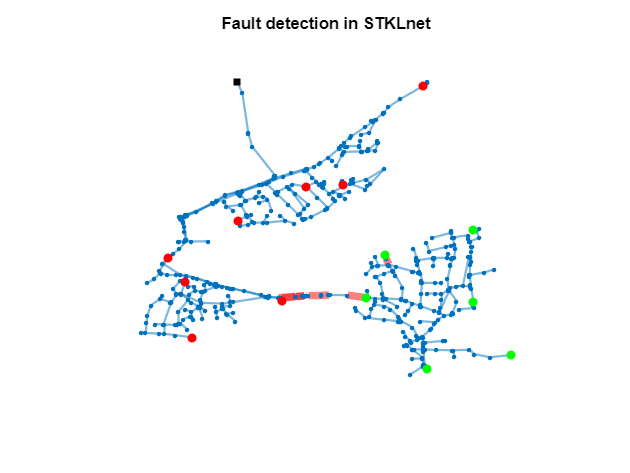

% sort the deviations in theta (delta_theta) and select 
% the 10 links most likely to correspond to the location 
% of the fault
[delta_theta_sort,fault_location] = sort(delta_theta);
fault_location = fault_location(1:10,1);

% define adjacency matrix AdjA of STKLnet
A = [A12,A10];
AdjA = sparse(size(A,2),size(A,2));
for k = 1:size(A,1)
    node_in = find(A(k,:)==-1);
    node_out = find(A(k,:)==1);
    AdjA(node_in,node_out) = 1;
    AdjA(node_out,node_in) = 1;
end
gr = graph(AdjA);

% represent the graph of the STKLnet network  
figure
p = plot(gr);
p.XData = wdn.XY(:,1);
p.YData = wdn.XY(:,2);
p.MarkerSize = 2;
p.LineWidth = 1.5;
hold on
% highlight the most likely locations of the detected fault
for loc = fault_location'
    highlight(p,find(A12(loc,:)==-1),find(A12(loc,:)==1),'EdgeColor','red','LineWidth',5);
    hold on 
end
% confirm the results of the parameter estimation problem 
% by highlighting the sensors where the largest pressure 
% deviations are observed
Sensor_fault = [All_Sensors(1,2),All_Sensors(1,9),All_Sensors(1,10),...
    All_Sensors(1,12),All_Sensors(1,13),All_Sensors(1,14)];
Sensor_normal = [All_Sensors(1,1),All_Sensors(1,3),All_Sensors(1,4),...
    All_Sensors(1,5),All_Sensors(1,6),...
    All_Sensors(1,7),All_Sensors(1,8),All_Sensors(1,11)];
highlight(p,Sensor_fault(1,:),'NodeColor','green','MarkerSize',5)
highlight(p,Sensor_normal(1,:),'NodeColor','red','MarkerSize',5)
highlight(p,909,'NodeColor','black','MarkerSize',5,'Marker','square')
p.NodeLabel = '';
axis('off')
title('Fault detection in STKLnet')

Question 5: Given your answers to Questions 3 and 4, comment on the possible nature of the fault. Finally, based on the results of the parameter estimation problem, recommend locations for further on-site investigation. Justify your answer (e.g., with a plot).

Answer 5: Given the answers to Questions 3 and 4, we can reach the conclusion that the fault behaves that the head loss in the STKLnet increases, which can be resulted from many reasons. The possibile nature of the fault includes the following:

- Firstly, it is also possible that we apply improper equation to construct the network model. Hazan-Williams headloss formula is more suitable in the place where there are no obvious terrain fluctuations. If the faulty location is not flat enough, it is possible that the simulated water head is higher, because in the real water supply network, the water head losses due to unstable topography.

- Secondly, in my opinion, the most possible reason for the head loss increase is the increase of pipe roughness, as the service time of water supply network becomes larger, the pipe becomes rougher and the cumulative head loss in the network also becomes larger, if the roughness coefficient we use to construct the model is obtained several years ago, we are quite possible to get the simulated pressure head based on a smoother pipe, which is wrong in real situation.

- Thirdly, if some pipes in the faulty location are even broken, the leakage becomes larger, the head loss will also increase.

- Fourthly, the failure of exhaust valve causes the increase of air resistance in the pipeline and leads to head loss increase.

- Finally, the physical property of water is the internal cause of head loss, thus if the property of water changes, the head loss will also increase, the possible reasons for the change may include,

- The aging of pipes, elbows and connecting tubes leads to the increase of water disorder, and  the extrusion and collision between water units leads to the increase of head loss.

- Changes in pipe diameter and flow rate lead to changes in the physical properties of water, and increases the head loss.

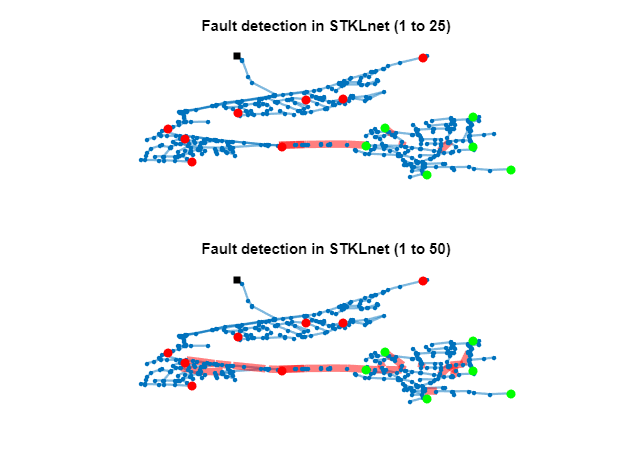

% Justify the location we have chosen
[delta_theta_sort_test,fault_location_test] = sort(delta_theta);
fault_location_test_1 = fault_location_test(1:25,1);
fault_location_test_2 = fault_location_test(1:50,1);

% plot the possible faulty pipeline (1 to 25)
subplot(2,1,1)
p = plot(gr);
p.XData = wdn.XY(:,1);
p.YData = wdn.XY(:,2);
p.MarkerSize = 2;
p.LineWidth = 1.5;
hold on
for loc = fault_location_test_1'
    highlight(p,find(A12(loc,:)==-1),find(A12(loc,:)==1),'EdgeColor','red','LineWidth',5);
    hold on 
end
highlight(p,Sensor_fault(1,:),'NodeColor','green','MarkerSize',5)
highlight(p,Sensor_normal(1,:),'NodeColor','red','MarkerSize',5)
highlight(p,909,'NodeColor','black','MarkerSize',5,'Marker','square')
p.NodeLabel = '';
axis('off')
title('Fault detection in STKLnet (1 to 25)')

% plot the possible faulty pipeline (1 to 50)
subplot(2,1,2)
p = plot(gr);
p.XData = wdn.XY(:,1);
p.YData = wdn.XY(:,2);
p.MarkerSize = 2;
p.LineWidth = 1.5;
hold on
for loc = fault_location_test_2'
    highlight(p,find(A12(loc,:)==-1),find(A12(loc,:)==1),'EdgeColor','red','LineWidth',5);
    hold on 
end
highlight(p,Sensor_fault(1,:),'NodeColor','green','MarkerSize',5)
highlight(p,Sensor_normal(1,:),'NodeColor','red','MarkerSize',5)
highlight(p,909,'NodeColor','black','MarkerSize',5,'Marker','square')
p.NodeLabel = '';
axis('off')
title('Fault detection in STKLnet (1 to 50)')

The locations for further on-site investigation I recommend would be the last red point connected to the westernmost green point and the pipeline between them. As we can see, the reservoir is in the southwest and the water flows through the pipe network. However, when it reaches the last red point in the graph (the point we have chosen), the 10 smallest delta_theta occurs after the node, which means that the roughness and the head loss, in the pipeline after that red point, increase. Therefore, that red point the the pipeline after it are quite possible to be out of order.

One thing we need to point out is that, although the errors after the westernmost green point also exist (Fault detection in STKLnet (1 to 25) and Fault detection in STKLnet (1 to 50)), such errors are more probable to result from cumulative effect after the faulty location.